close all
clear variables

testFo = 120;
fmCent = 20;
fl = 80;
fh = 400;
nOct = 48;
outDirName = "/Volumes/SSPL-UT/testCAPRICEP/";
handle1 = figure;
output = fmTransfTestGaussNCyc(testFo, fmCent, @pitchCEP);

dataOut = makePitchTestMovie(fl, fh, nOct, fmCent, @pitchNCF);

nFo = length(dataOut);
titleStr = output.testCondStr.titleStr;
foList = fl * 2 .^ (0:1/nOct:log2(fh/fl));
figure;
set(gcf, 'position', [681   700   960   540])
fxSeg = output.fxSeg;
fxSeg(1) = fxSeg(2)/1000000;
for ii = 1:nFo
    output = dataOut(ii).output;
    respLTI = 20*log10(abs(output.averageResponse));
    respTVI = 10*log10(output.varTV);
    respNLTI = 10*log10(output.varNLTI);
    semilogx(fxSeg, respLTI([2 2:end]), 'linewidth', 3);
    hold all;
    semilogx(fxSeg, respTVI([2 2:end]), 'linewidth', 3);
    semilogx(fxSeg, respNLTI([2 2:end]), 'linewidth', 3);
    grid on;
    set(gca, 'fontsize', 15, 'linewidth', 2)
    axis([1 100 -100 10])
    title(titleStr + " fo:" + num2str(foList(ii), '%7.1f') + " Hz, FMdpth:" ...
        + num2str(fmCent, '%7.1f') + " cent, narrow Gauss:");
    xlabel('frequency (Hz)')
    ylabel('gain (dB)')
    text(35, -90, titleStr, 'FontSize', 32)
    legend('LTI', 'TV-rand', 'non-LTI', 'location', 'south','Orientation','horizontal', 'fontsize', 15);
    drawnow
    hold off
end

使い方によるエラー abs
入力引数が多すぎます。

dataOutNINJAL = makePitchTestMovie(fl, fh, nOct, fmCent, @pitchNINJAL);

figure;
set(gcf, 'position', [681   700   1920   1080])
tiledlayout(2,2);
tileStrB = struct;
for ii = 1:4
    tileStrB(ii).t = nexttile;
end
mkdir(outDirName + "fourMovie4")

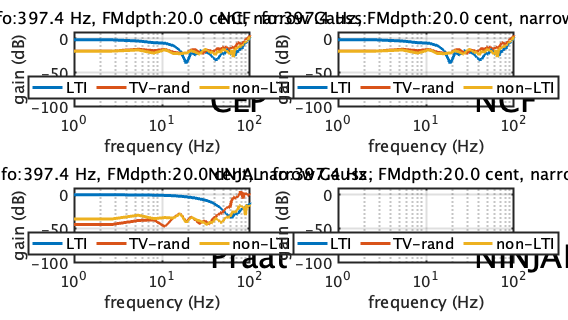

for ii = 1:nFo
    for jj = 1:4
        t1 = tileStrB(jj).t;
        switch jj
            case 1
                titleStr = "CEP ";
                dataOut = dataOutCEP;
            case 2
                titleStr = "NCF ";
                dataOut = dataOutNCF;
            case 3
                titleStr = "Praat ";
                dataOut = dataOutPraat;
            case 4
                titleStr = "NINJAL ";
                dataOut = dataOutNINJAL;
        end
        axes(t1)
        output = dataOut(ii).output;
        respLTI = 20*log10(abs(output.averageResponse));
        respTVI = 10*log10(output.varTV);
        respNLTI = 10*log10(output.varNLTI);
        semilogx(fxSeg, respLTI([2 2:end]), 'linewidth', 3);
        hold all;
        semilogx(fxSeg, respTVI([2 2:end]), 'linewidth', 3);
        semilogx(fxSeg, respNLTI([2 2:end]), 'linewidth', 3);
        grid on;
        set(gca, 'fontsize', 15, 'linewidth', 2)
        axis([1 100 -100 10])
        title(titleStr + " fo:" + num2str(foList(ii), '%7.1f') + " Hz, FMdpth:" ...
            + num2str(fmCent, '%7.1f') + " cent, narrow Gauss:");
        xlabel('frequency (Hz)')
        ylabel('gain (dB)')
        text(35, -90, titleStr, 'FontSize', 32)
        legend('LTI', 'TV-rand', 'non-LTI', 'location', 'south','Orientation','horizontal', 'fontsize', 15);
        drawnow
        hold off
    end
    outname = outDirName + "fourMovie4/" + "pic" + num2str(ii,'%04.0f') + ".png";
    print('-dpng','-r100',outname);
end

outpuCEP = dataOutCEP.output;
outputHarvest = dataOutHarvest.output;
outputNCF = dataOutNCF.output;
outputNINJAL = dataOutNINJAL.output;
outputPraat = dataOutPraat.output;
%save outputDataSet outputPraat outputNINJAL outputNCF outputHarvest outpuCEP

